%% Dual Quaternion Basics Part 2 - Homework
% File: dual_quaternion_basics_part2_homework.m

%% Homework example
% Clean up routine to remove variables from your workspace
clear all;
close all;

%% Initialize the DQ Robotics namespace
include_namespace_dq

%% Solutions
%% Question 1
% Find the Plucker line representing y-axis using four different point pairs

fprintf('Question 1: Plucker lines for y-axis\n');

Question 1: Plucker lines for y-axis



% Line 1: using points (0,0,0) and (0,1,0)
p1_1 = DQ([0, 0, 0, 0]);
p1_2 = DQ([0, 0, 1, 0]);
l_1 = p1_1 - p1_2;
fprintf('l_1: '); disp(l_1);

l_1:   DQ with properties:

              q: [8×1 double]
    handle_axis: []
    handle_text: []
         isplot: []
              E: [1×1 DQ]
              i: [1×1 DQ]
              j: [1×1 DQ]
              k: [1×1 DQ]
      threshold: 1.0000e-12
             C8: [8×8 double]
             C4: [4×4 double]




% Line 2: using points (0,-1,0) and (0,1,0)
p2_1 = DQ([0, 0, -1, 0]);
p2_2 = DQ([0, 0, 1, 0]);
l_2 = p2_1 - p2_2;
fprintf('l_2: '); disp(l_2);

l_2:   DQ with properties:

              q: [8×1 double]
    handle_axis: []
    handle_text: []
         isplot: []
              E: [1×1 DQ]
              i: [1×1 DQ]
              j: [1×1 DQ]
              k: [1×1 DQ]
      threshold: 1.0000e-12
             C8: [8×8 double]
             C4: [4×4 double]




% Line 3: using points (0,2,0) and (0,5,0)
p3_1 = DQ([0, 0, 2, 0]);
p3_2 = DQ([0, 0, 5, 0]);
l_3 = p3_1 - p3_2;
fprintf('l_3: '); disp(l_3);

l_3:   DQ with properties:

              q: [8×1 double]
    handle_axis: []
    handle_text: []
         isplot: []
              E: [1×1 DQ]
              i: [1×1 DQ]
              j: [1×1 DQ]
              k: [1×1 DQ]
      threshold: 1.0000e-12
             C8: [8×8 double]
             C4: [4×4 double]




% Line 4: using points (0,-3,0) and (0,4,0)
p4_1 = DQ([0, 0, -3, 0]);
p4_2 = DQ([0, 0, 4, 0]);
l_4 = p4_1 - p4_2;
fprintf('l_4: '); disp(l_4);

l_4:   DQ with properties:

              q: [8×1 double]
    handle_axis: []
    handle_text: []
         isplot: []
              E: [1×1 DQ]
              i: [1×1 DQ]
              j: [1×1 DQ]
              k: [1×1 DQ]
      threshold: 1.0000e-12
             C8: [8×8 double]
             C4: [4×4 double]




fprintf('Are all Plucker lines the same?\n');

Are all Plucker lines the same?


fprintf('They represent the same geometric line but may differ in magnitude.\n\n');

They represent the same geometric line but may differ in magnitude.




%% Question 2
% Define point p1 and calculate distance to l_1

p_1 = DQ([0, 1, 2, 3]);
fprintf('Question 2:\n');

Question 2:


fprintf('Point p_1 = (1, 2, 3)\n');

Point p_1 = (1, 2, 3)



distance_p1_to_l1 = norm(cross(P(l_1), p_1));
fprintf('Distance from p_1 to l_1: %.4f\n\n', distance_p1_to_l1);

Distance from p_1 to l_1: 3.1623




%% Question 3
% Find y-z plane using two possible normals

fprintf('Question 3: Y-Z plane\n');

Question 3: Y-Z plane



% Normal pointing in +x direction
n_pos = DQ([0, 1, 0, 0]);
pi_1 = n_pos + E_ * 0 * n_pos;
fprintf('pi_1 (normal in +x): '); disp(pi_1);

pi_1 (normal in +x):   DQ with properties:

              q: [8×1 double]
    handle_axis: []
    handle_text: []
         isplot: []
              E: [1×1 DQ]
              i: [1×1 DQ]
              j: [1×1 DQ]
              k: [1×1 DQ]
      threshold: 1.0000e-12
             C8: [8×8 double]
             C4: [4×4 double]




% Normal pointing in -x direction
n_neg = DQ([0, -1, 0, 0]);
pi_2 = n_neg + E_ * 0 * n_neg;
fprintf('pi_2 (normal in -x): '); disp(pi_2);

pi_2 (normal in -x):   DQ with properties:

              q: [8×1 double]
    handle_axis: []
    handle_text: []
         isplot: []
              E: [1×1 DQ]
              i: [1×1 DQ]
              j: [1×1 DQ]
              k: [1×1 DQ]
      threshold: 1.0000e-12
             C8: [8×8 double]
             C4: [4×4 double]



fprintf('\n');

%% Question 4
% Calculate distances between p1 and the two planes

fprintf('Question 4:\n');

Question 4:



dist_p1_to_pi1 = dot(p_1, pi_1);
if isa(dist_p1_to_pi1, 'DQ')
    dist_p1_to_pi1 = vec8(dist_p1_to_pi1);
    dist_p1_to_pi1 = dist_p1_to_pi1(1);
end
fprintf('Distance from p_1 to pi_1: %.4f\n', dist_p1_to_pi1);

Distance from p_1 to pi_1: 1.0000



dist_p1_to_pi2 = dot(p_1, pi_2);
if isa(dist_p1_to_pi2, 'DQ')
    dist_p1_to_pi2 = vec8(dist_p1_to_pi2);
    dist_p1_to_pi2 = dist_p1_to_pi2(1);
end
fprintf('Distance from p_1 to pi_2: %.4f\n', dist_p1_to_pi2);

Distance from p_1 to pi_2: -1.0000



if sign(dist_p1_to_pi1) ~= sign(dist_p1_to_pi2)
    fprintf('Signs are different\n');
else
    fprintf('Signs are the same\n');
end

Signs are different


fprintf('Why? The signed distance depends on normal direction.\n');

Why? The signed distance depends on normal direction.


fprintf('Point p_1 is on the positive x-side, so distance is positive with\n');

Point p_1 is on the positive x-side, so distance is positive with


fprintf('+x normal and negative with -x normal.\n\n');

+x normal and negative with -x normal.




%% Question 5
% Build 5mx5mx5m cubic region with 6 planes

fprintf('Question 5: Cubic region\n');

Question 5: Cubic region



half = 2.5;

% Six planes with normals pointing towards origin
pi_3 = DQ([0, -1, 0, 0]) + E_ * half * DQ([0, -1, 0, 0]);  % x = 2.5
pi_4 = DQ([0, 1, 0, 0]) + E_ * half * DQ([0, 1, 0, 0]);    % x = -2.5
pi_5 = DQ([0, 0, -1, 0]) + E_ * half * DQ([0, 0, -1, 0]);  % y = 2.5
pi_6 = DQ([0, 0, 1, 0]) + E_ * half * DQ([0, 0, 1, 0]);    % y = -2.5
pi_7 = DQ([0, 0, 0, -1]) + E_ * half * DQ([0, 0, 0, -1]);  % z = 2.5
pi_8 = DQ([0, 0, 0, 1]) + E_ * half * DQ([0, 0, 0, 1]);    % z = -2.5

fprintf('Created 6 planes for 5x5x5 cube\n');

Created 6 planes for 5x5x5 cube


fprintf('All normals point towards origin\n\n');

All normals point towards origin



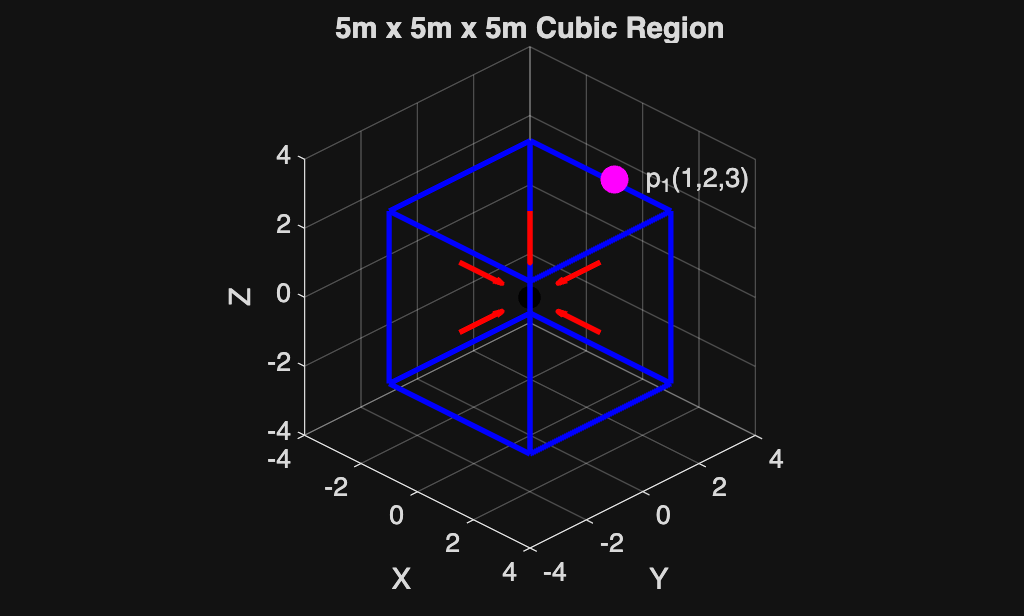


% Plot the cubic region
figure('Name', 'Cubic Region');
hold on; grid on; axis equal;
xlabel('X'); ylabel('Y'); zlabel('Z');
title('5m x 5m x 5m Cubic Region');
view(45, 30);

% Cube vertices
v = [-half, -half, -half;
      half, -half, -half;
      half,  half, -half;
     -half,  half, -half;
     -half, -half,  half;
      half, -half,  half;
      half,  half,  half;
     -half,  half,  half];

% Edges
edges = [1,2; 2,3; 3,4; 4,1;
         5,6; 6,7; 7,8; 8,5;
         1,5; 2,6; 3,7; 4,8];

for i = 1:size(edges, 1)
    plot3([v(edges(i,1),1), v(edges(i,2),1)], ...
          [v(edges(i,1),2), v(edges(i,2),2)], ...
          [v(edges(i,1),3), v(edges(i,2),3)], 'b-', 'LineWidth', 2);
end

% Plane centers and normals
centers = [half, 0, 0; -half, 0, 0; 0, half, 0; 
           0, -half, 0; 0, 0, half; 0, 0, -half];
normals = [-1, 0, 0; 1, 0, 0; 0, -1, 0; 
           0, 1, 0; 0, 0, -1; 0, 0, 1];

for i = 1:6
    quiver3(centers(i,1), centers(i,2), centers(i,3), ...
            normals(i,1)*1.5, normals(i,2)*1.5, normals(i,3)*1.5, ...
            0, 'r', 'LineWidth', 2, 'MaxHeadSize', 0.5);
end

% Plot origin
plot3(0, 0, 0, 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'k');

% Plot point p1
p1_coords = vec3(p_1);
plot3(p1_coords(1), p1_coords(2), p1_coords(3), 'mo', ...
      'MarkerSize', 10, 'MarkerFaceColor', 'm');
text(p1_coords(1), p1_coords(2), p1_coords(3), '  p_1(1,2,3)');

xlim([-4, 4]); ylim([-4, 4]); zlim([-4, 4]);
hold off;


%% Question 6
% Find closest plane to p1

fprintf('Question 6: Closest plane to p_1\n');

Question 6: Closest plane to p_1



planes = {pi_3, pi_4, pi_5, pi_6, pi_7, pi_8};
names = {'pi_3', 'pi_4', 'pi_5', 'pi_6', 'pi_7', 'pi_8'};
distances = zeros(1, 6);

for i = 1:6
    d = dot(p_1, planes{i});
    if isa(d, 'DQ')
        d = vec8(d);
        d = d(1);
    end
    distances(i) = abs(d);
    fprintf('Distance to %s: %.4f\n', names{i}, distances(i));
end

Distance to pi_3: 1.0000
Distance to pi_4: 1.0000
Distance to pi_5: 2.0000
Distance to pi_6: 2.0000
Distance to pi_7: 3.0000
Distance to pi_8: 3.0000



[min_dist, idx] = min(distances);
fprintf('\nClosest plane: %s\n', names{idx});


Closest plane: pi_3


fprintf('Distance: %.4f m\n', min_dist);

Distance: 1.0000 m



fprintf('\nHomework complete!\n');


Homework complete!
